% Mathematical Models and Methods for Image Processing
% Giacomo Boracchi, Diego Carrera
% May 2022
%
% Politecnico di Milano
% giacomo.boracchi@polimi.it
%
seed = 1234

seed = 1234

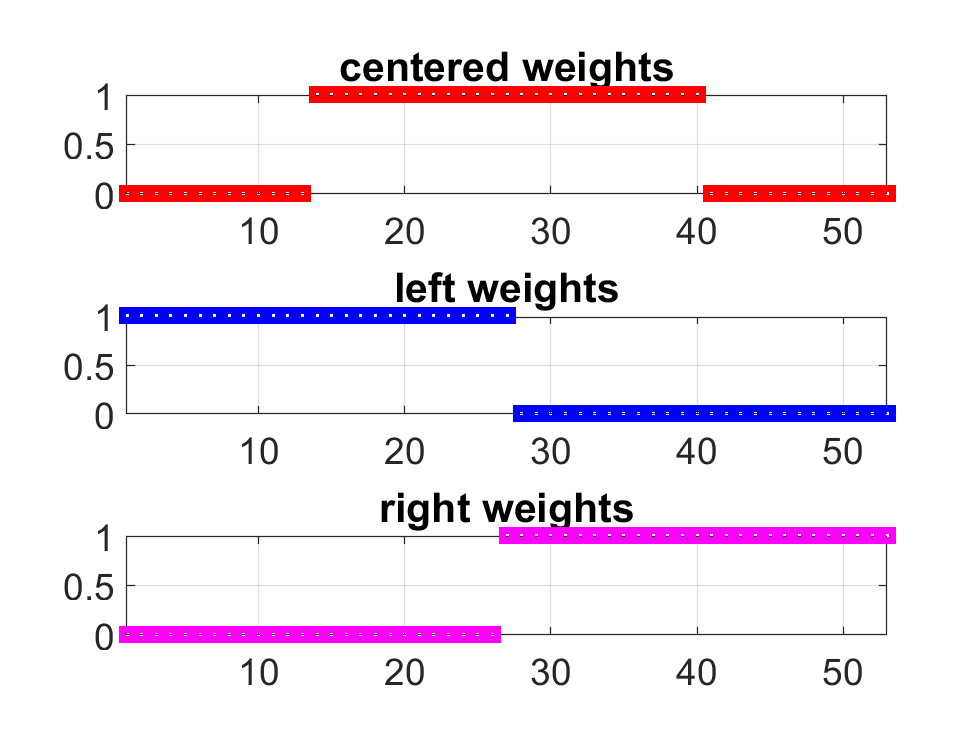

rng(seed)

clear
close all
clc

%% Set the LPA parameters

% maximum degree of polynomial used for fitting
N = 2;

% filter size
M = 53;
% half filter size
HFS = floor(M/2);

% Set the weights. Here weights simply define the window size 
w = zeros(M, 1);

% centered kernel
wc = w;
wc([floor(HFS /2) + 1 : end - floor(HFS/2) ]) = 1;

wl = w;
wl([1 : HFS + 1]) = 1;

wr = w;
wr([HFS + 1 : end]) = 1;

FNT_SZ = 16;

figure(1),
subplot(3,1,1),
plot(wc, 'rs', 'LineWidth', 3), title('centered weights'), grid on, axis tight
set(gca,'FontSize', FNT_SZ)
subplot(3,1,2),
plot(wl, 'bs', 'LineWidth', 3), title('left weights'), grid on, axis tight
set(gca,'FontSize', FNT_SZ)
subplot(3,1,3),
plot(wr, 'ms', 'LineWidth', 3), title('right weights'), grid on, axis tight
set(gca,'FontSize', FNT_SZ)


%modify here to select a single weight to be used in what follows
w = wc;

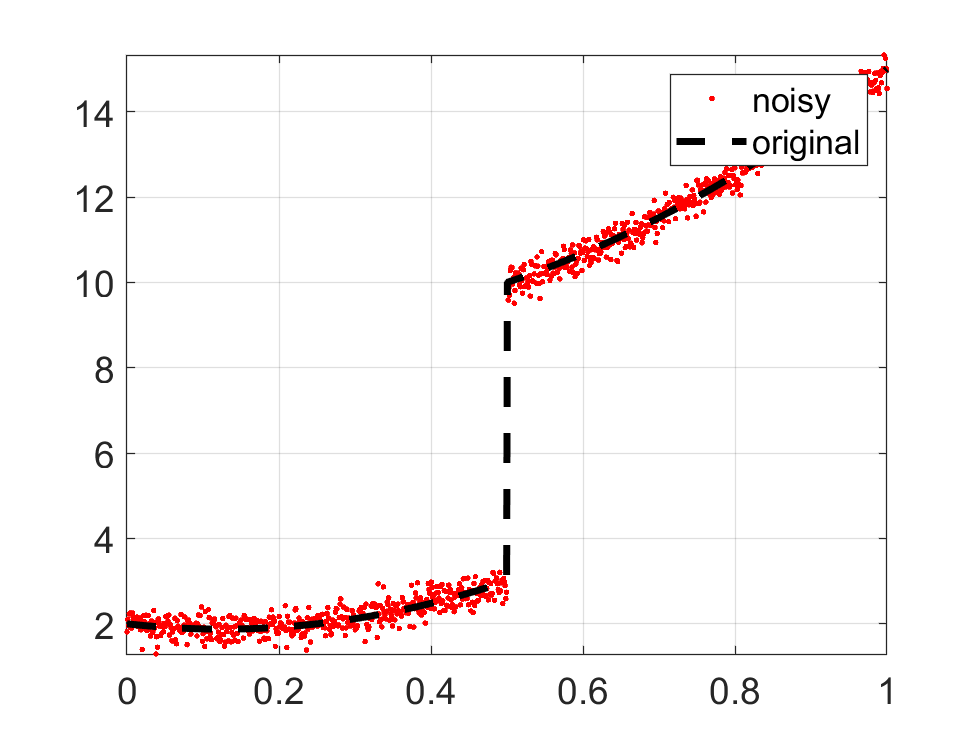

%% Generate Signal
% Generate the entire signal
LENGTH = 1000;
[y, ty] = get_synthetic_signal('parabolas', LENGTH);

% noise standard deviation
sigma = 0.2;

% noisy signal 
s = y + sigma*randn(size(y));

figure(2), 
plot(ty, s, 'r.');
hold on
plot(ty, y, 'k--', 'LineWidth', 3);
hold off
grid on
axis tight
set(gca,'FontSize', FNT_SZ)
legend('noisy', 'original')

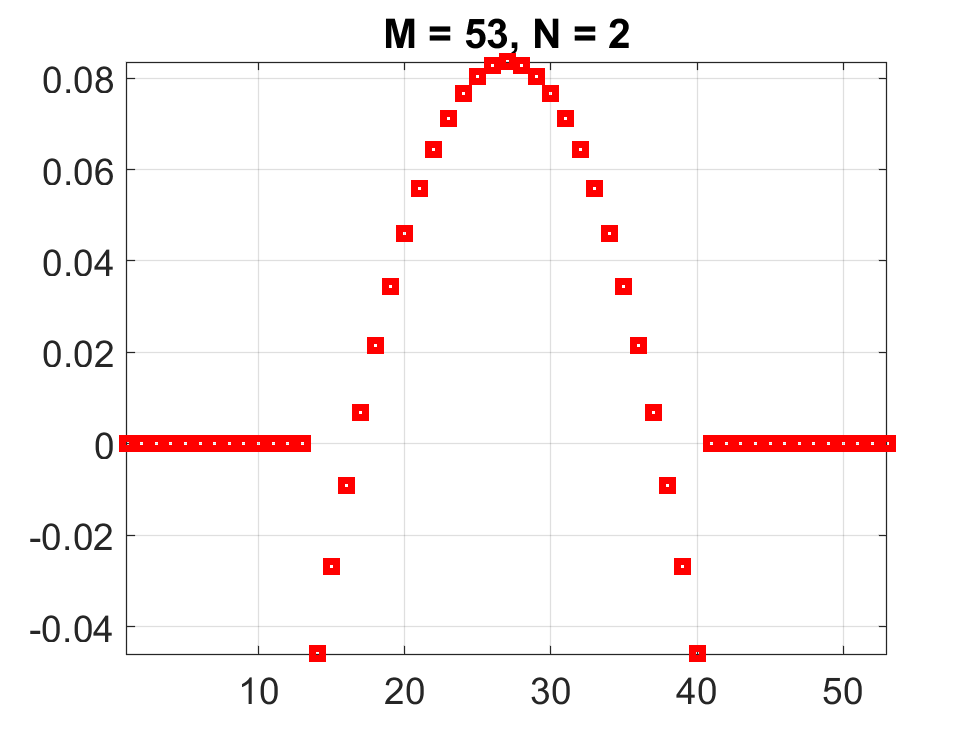

plot_T = false;
g = compute_LPA_kernel(w, N, ty, plot_T);

figure(4),
plot(g, 'rs', 'LineWidth', 3), title('filter'), grid on, axis tight
set(gca,'FontSize', FNT_SZ)
title(['M = ', num2str(M), ', N = ', num2str(N)])

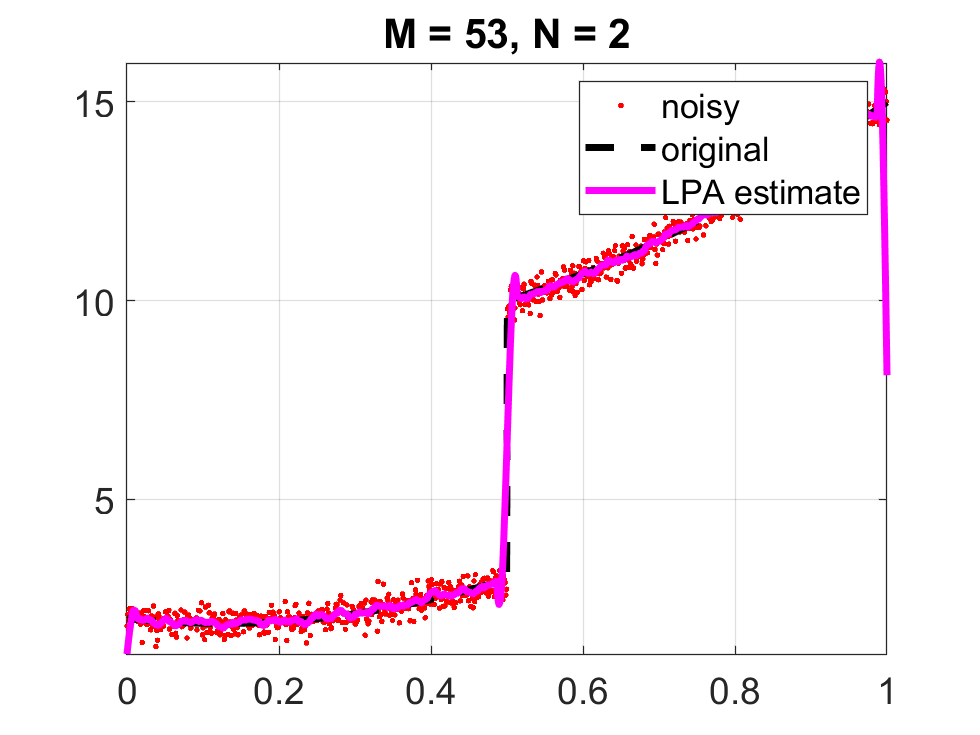

%% FITERING

shat = conv(s,g, "same");

figure(5),  
plot(ty, s, 'r.');
hold on
plot(ty, y, 'k--', 'LineWidth', 3);
plot(ty, shat, 'm-','LineWidth', 3);
hold off
grid on
axis tight
title(['M = ', num2str(M), ', N = ', num2str(N)])
set(gca,'FontSize', FNT_SZ)
legend('noisy', 'original', 'LPA estimate');